clear all 
clc

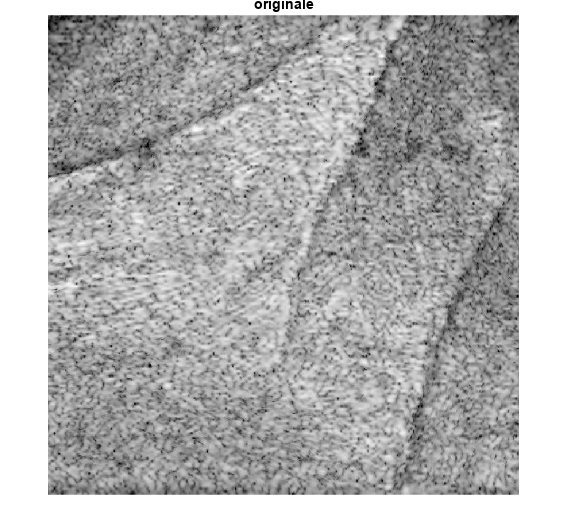

im = fullfile("imageGeneratedFrom3D/Luongo_1_rimozioneRes_000/immagine_6_0.3234.jpg");
I = imread(im);
originale = I;
imshow(I);title('originale');figure;

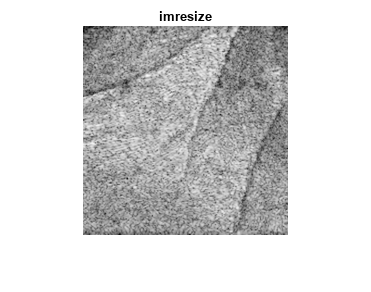

%RESIZE DELL'IMMAGINE
im1=imresize(I, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
% im1=imresize(im1, 1.2, 'bicubic');
imshow(im1);title('imresize');figure;

[dim1, dim2] = size(im1);
fprintf('Dimensione immagine: %.0f x %.0f', dim1, dim2);

Dimensione immagine: 209 x 205

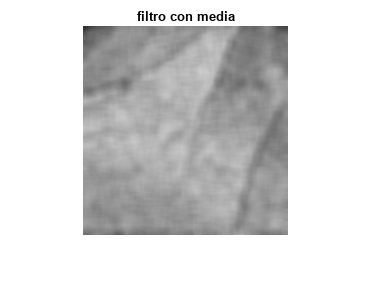

%APPLICAZIONE FILTRO MEDIA
H = fspecial("average",10);
gssmooth = imfilter(im1,H,"replicate");
imshow(gssmooth); title('filtro con media'); figure;

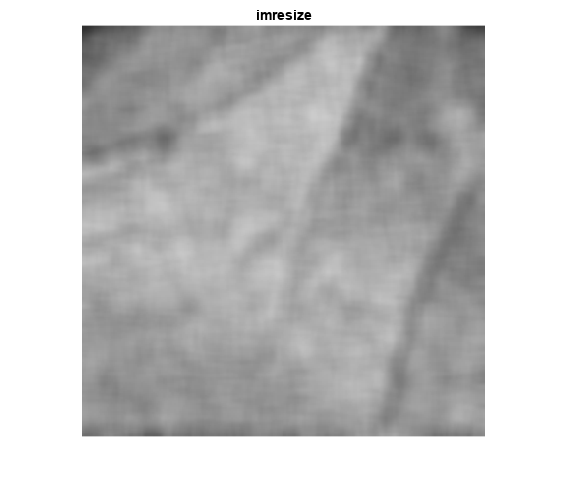

im1=imresize(gssmooth, 2, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
% im1=imresize(im1, 1.2, 'bicubic');
imshow(im1);title('imresize');figure;

[dim1, dim2] = size(im1);
fprintf('Dimensione immagine: %.0f x %.0f', dim1, dim2);

Dimensione immagine: 418 x 410

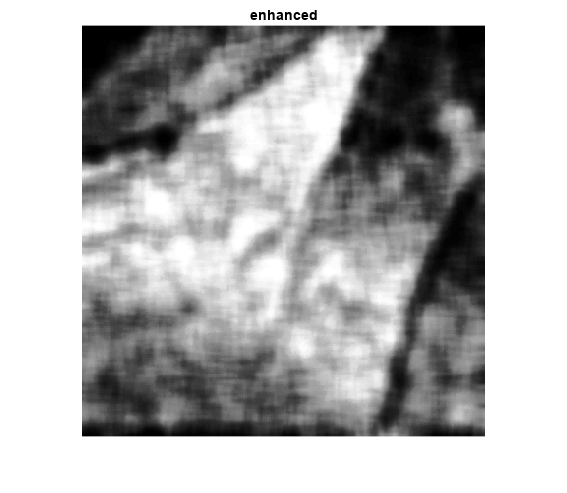


enhanced = histeq(im1);
imshow(enhanced); title('enhanced'); figure;

%BINARIZZAZIONE
% A = im1;
% % meanValue=mean2(A);
% meanValue = imbinarize(A, "adaptive", "ForegroundPolarity","dark");
% % threshold = meanValue*1.6; %più è alto il fattore di scala meno dettagli saranno presenti
%  
% % A_bw = A > threshold;
% imshow(meanValue); title('binarizzazione'); figure;

% %AUMENTO CONTRASTO
% contrastAdjusted = imadjust(double(meanValue));
% imshow(contrastAdjusted); title('ContrastAdjusted'); figure;


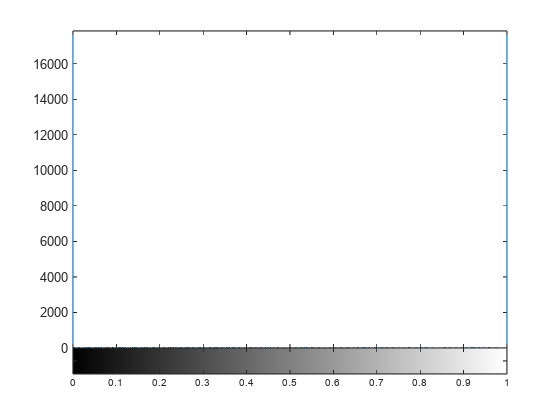

%APPLICAZIONE FILTRO DoG
gaussian1 = fspecial('gaussian',32,5); 
gaussian2 = fspecial('gaussian',32,10);
gaussian = gaussian2 - gaussian1;
dogFilterImage2 = conv2(double(enhanced), gaussian, 'same');

imhist(dogFilterImage2)

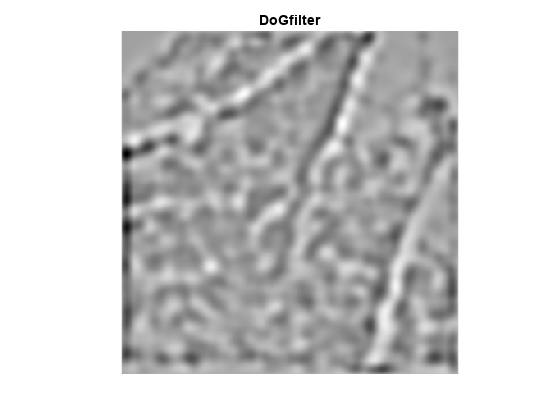

imshow(dogFilterImage2,[]);title('DoGfilter');figure;

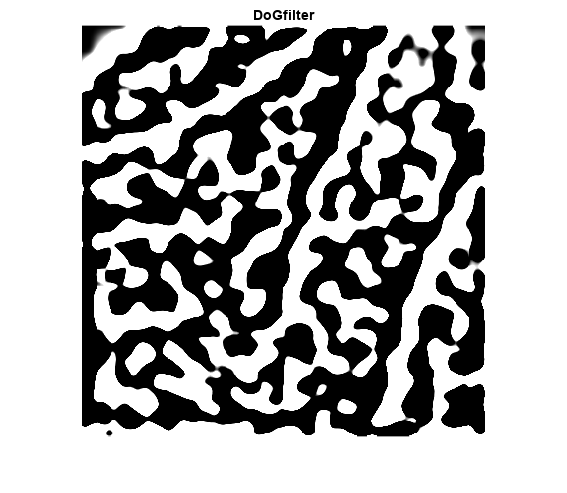

dogFilterImage2 = imadjust(double(dogFilterImage2),[0 0.5]);
imshow(dogFilterImage2,[]);title('DoGfilter');figure;

% %AUMENTO CONTRASTO
% contrastAdjusted = imadjust(double(dogFilterImage2));
% imshow(contrastAdjusted); title('ContrastAdjusted'); figure;

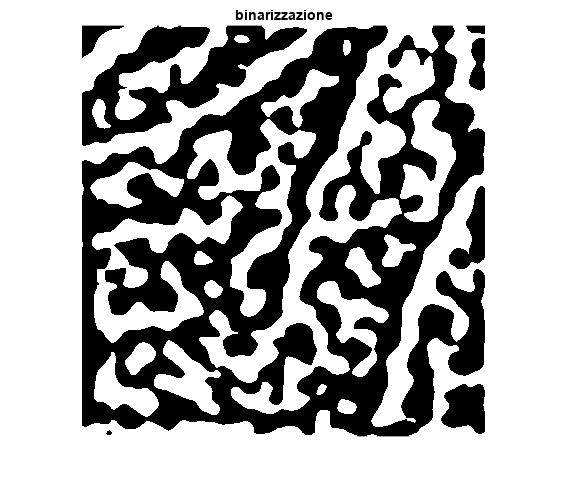

%BINARIZZAZIONE
A = dogFilterImage2;
% meanValue=mean2(A);
% meanValue = imbinarize(A, "adaptive", "ForegroundPolarity","dark");
meanValue = imbinarize(A);
% threshold = meanValue*1.6; %più è alto il fattore di scala meno dettagli saranno presenti
% 
% A_bw = A > threshold;
imshow(meanValue); title('binarizzazione'); figure;

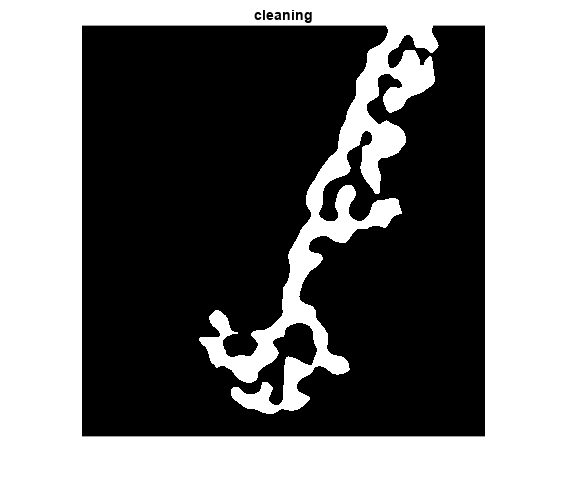

%CLEANING
CC= bwconncomp(meanValue);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW2 = ismember(L, find([S.Area] >= 12000));
imshow(BW2); title('cleaning'); figure;

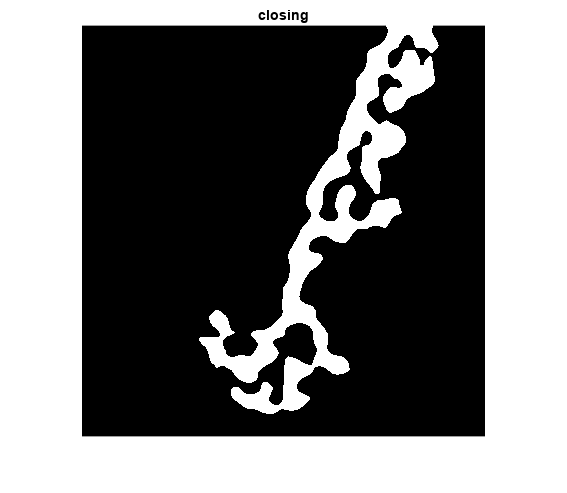

%CLOSING
se=strel('disk',1);
closing=imopen(BW2, se);
imshow(closing); title('closing'); figure;

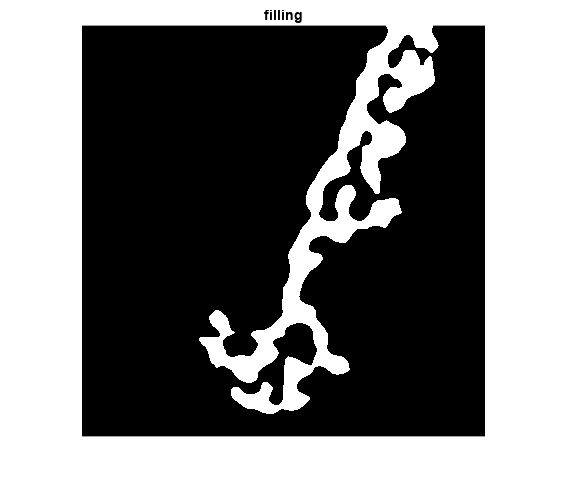

% FILLING
filling= imfill(closing, 'holes');
imshow(filling);title('filling');figure;

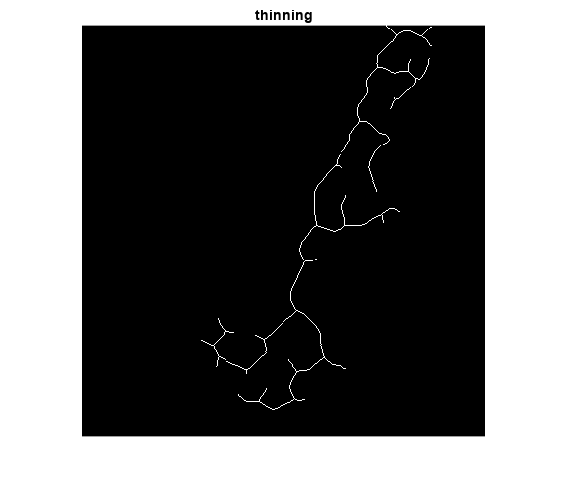

%THINNING
thinning= bwmorph(filling, 'thin', inf);
imshow(thinning);title('thinning');figure;

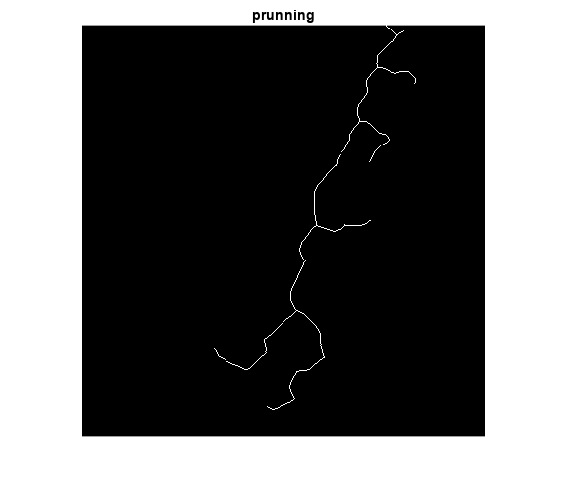

%PRUNNING
prun= bwmorph( thinning, 'spur', 30);
imshow(prun);title('prunning');figure;

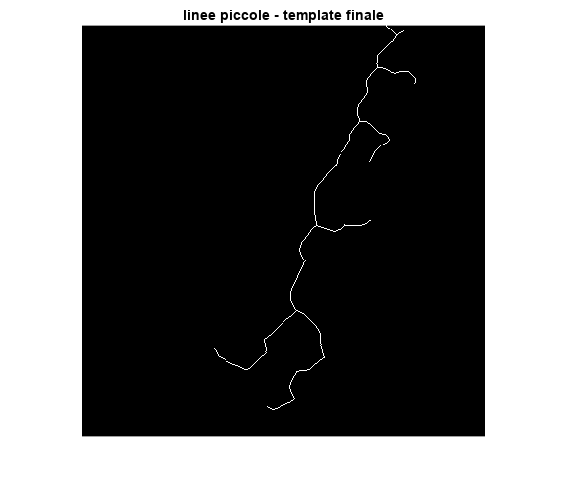

%CLEANING LINEE PICCOLE
BWz = bwareaopen(prun, 20);
imshow(BWz);title('linee piccole - template finale');figure;

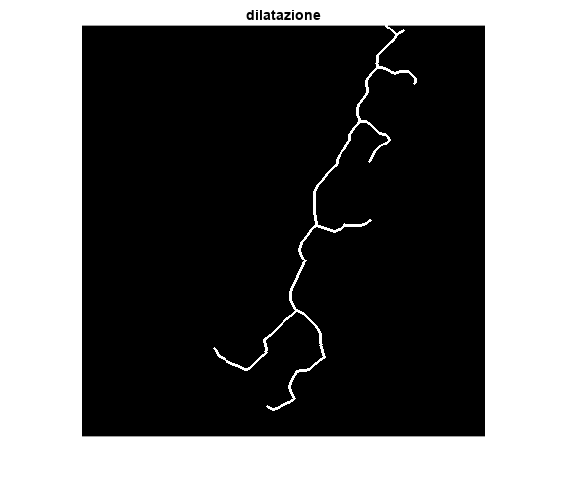

%DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
dilatation_mask= strel('disk', 1);
dilatedImageDat= imdilate(BWz, dilatation_mask);
imshow(dilatedImageDat); title('dilatazione'); figure;

originale = imresize(originale, 0.5, 'bicubic');
rgbImage = cat(3, originale, originale, originale);



%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
clear m n1

[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImageDat(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=255;
        rgbImage(i,j,3)=255;
        end 
    end 
 end	 


imshowpair(rgbImage, I, 'montage');title('sovrapposizone'); figure;

Unrecognized function or variable 'imshwpair'.